# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.6 散点、拟合线、误差线

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/529194379/answer/2457512221](https://www.zhihu.com/question/529194379/answer/2457512221)

# 这种图要用什么软件做？具体有哪些步骤呢？

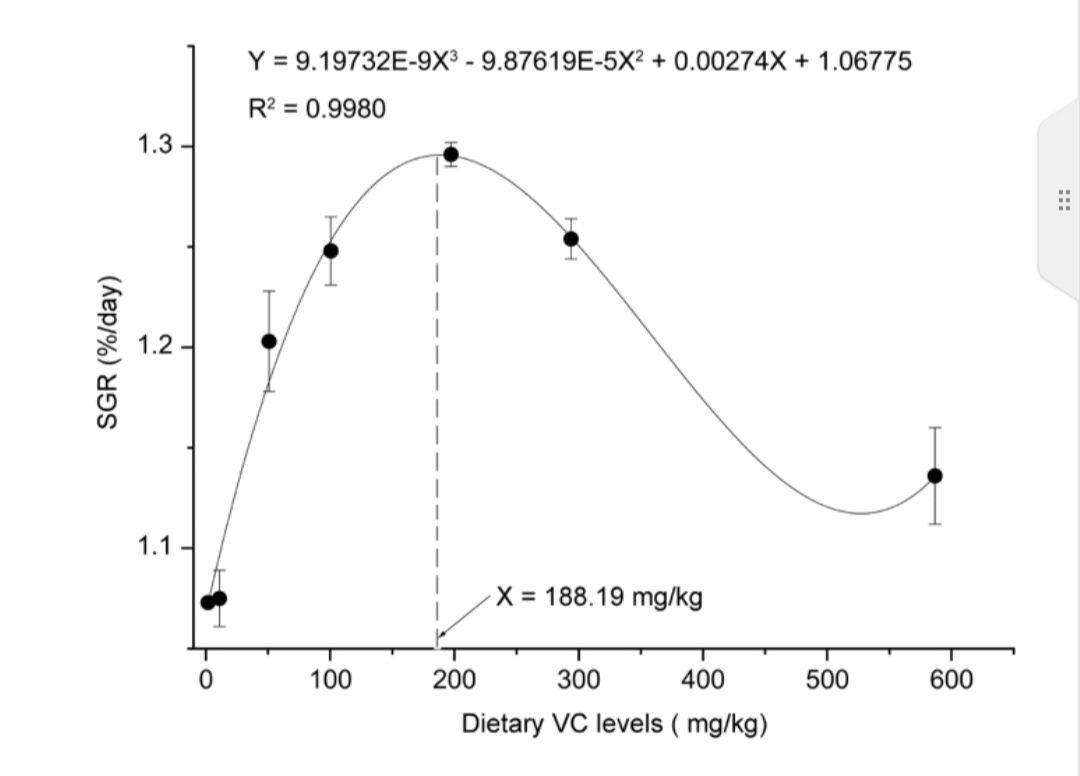

clear;clc;
data = load('data\FittingPoints.txt');
x = data(:, 1);
% 貌似第一个点是从 0 开始的
x = x - x(1);
y = data(:, 2);
% 三次多项式拟合
p = polyfit(x, y, 3);
fprintf('%e  %e  %e  %e', p(1), p(2), p(3), p(4));

1.060506e-08  -1.096983e-05  2.917243e-03  1.065545e+00

% 计算拟合值
yfit = polyval(p, x);
% 计算 R2
R2 = sum((yfit - mean(y)).^2) / sum((y - mean(y)).^2)

R2 = 0.9824

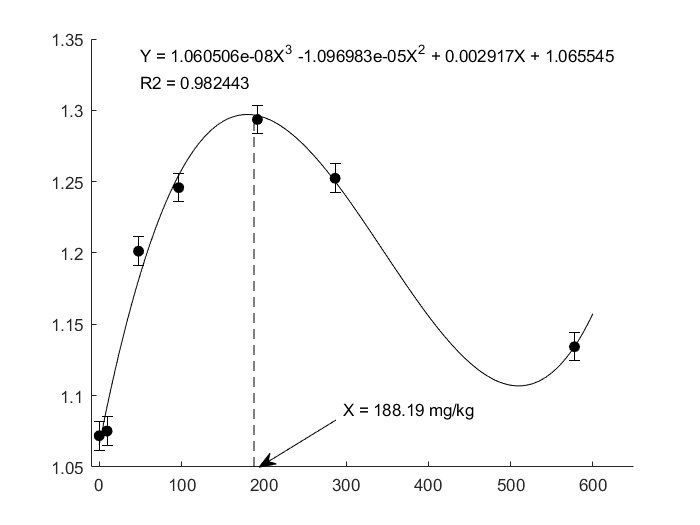

% 计算拟合曲线
xx = 0:1:600;
yy = polyval(p, xx);

% 画图
plot(x, y, 'ok', 'MarkerFaceColor', 'k');
hold on
plot(xx, yy, 'k');
% 误差线 怎么算的？
err = 0.01 * ones(size(x));
errorbar(x, y, err, '.k');
% 还有中间一条虚线
x0 = 188.19;
y0 = polyval(p, x0);
plot([x0, x0], [1.05, y0], '--k');
% 箭头文本 这个坐标是 [0, 1] 之间的，可以转换过来
annotation('textarrow', [0.48, 0.37], [0.2, 0.11], 'String', 'X = 188.19 mg/kg');
hold off
xlim([-10, 650]);
% 还有啥 拟合公式
text(50, 1.34, sprintf('Y = %eX^3 %eX^2 + %fX + %f', p(1), p(2), p(3), p(4)));
% R2
text(50, 1.32, sprintf('R2 = %f', R2));
box off